## **module 1 **

## **working with 2D images**

to import your 2D image use the function **medicalImage("file path")** 

the function gives you all the metadata needed 

window width and window center are the two values that show you the proper values of brightness and contrast (window center control brightness and window width controls contrast) 

### why do I need to change the value of contrast and brightness?

because we have different data types and different formats for showing

medical images, each format uses different range of values 

ex: to show an x-ray of bone you will need different range from showing tissue

scan using MRI. 

the numerical format of medical image should with the physics of the scan

(take a look on what are 8bit, 16bit, int16...etc)

 it also shows you the modality of taking the image here it's computed

 radiography or x ray



a = medicalImage("D:\matlab\coursera_content\Medical Image Processing (1)\Data\Xray Images\back view02.dcm")

a =   medicalImage with properties:

          Pixels: [3028×1676 uint16]
        Colormap: []
    SpatialUnits: "mm"
       FrameTime: []
       NumFrames: 1
    PixelSpacing: [0.1390 0.1390]
        Modality: 'CR'
    WindowCenter: 2048
     WindowWidth: 4096


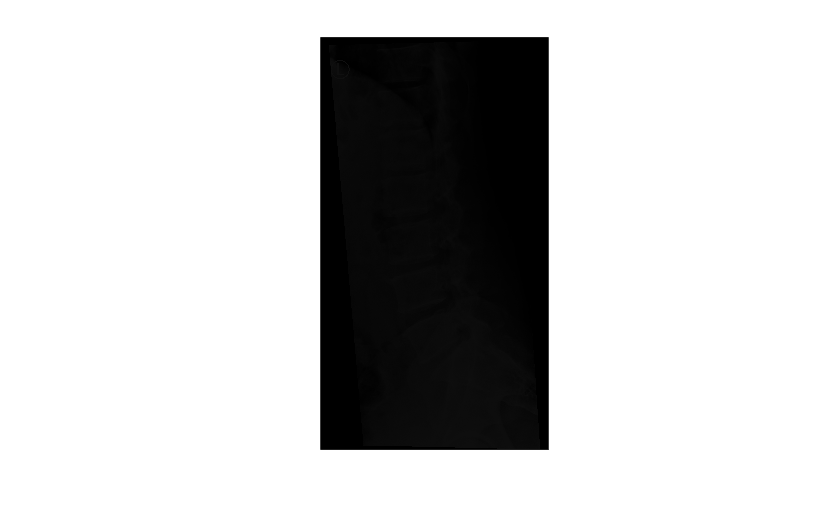

%{
 use extractframe('your_image_title') function to give you the number of
frames + imshow function for showing the image as image not metadata 

%}

img = extractFrame(a,1);
imshow(img) %the first input of imshow is your extracted img

#### **fix the range of your window center and window width** 

to reveal more details 

- from "image viewer app" 

- using min amd max values of your window width and window center to fit your image to the correct range of  brightness and contrast 



min_value = a.WindowCenter - a.WindowWidth /2

min_value = 0

max_value = a.WindowCenter + a.WindowWidth /2 

max_value = 4096

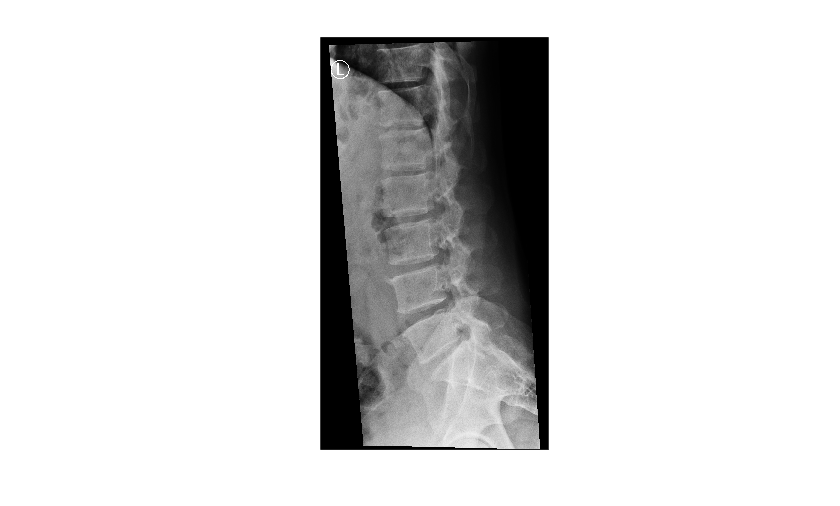

% give your min and max as a seconed input to imshow function
imshow(img, [min_value, max_value])

measurement tool helps you measure **different parts** of your img. 

use image viewer app, 

- go to measurements

- select the desired part you need to measure, 

- export measures D1 variable 

note: we will use the measure value only so we will call it ** D1.value**

**pixelspacing **function is used to change the value from pixels to mm


the_value_mm = D1.Value * a.PixelSpacing(1)

the_value_mm = 78.7809

% adjust your contrast and brightness range to the datatype range using  imadjust if you need to adjust all images to the same range

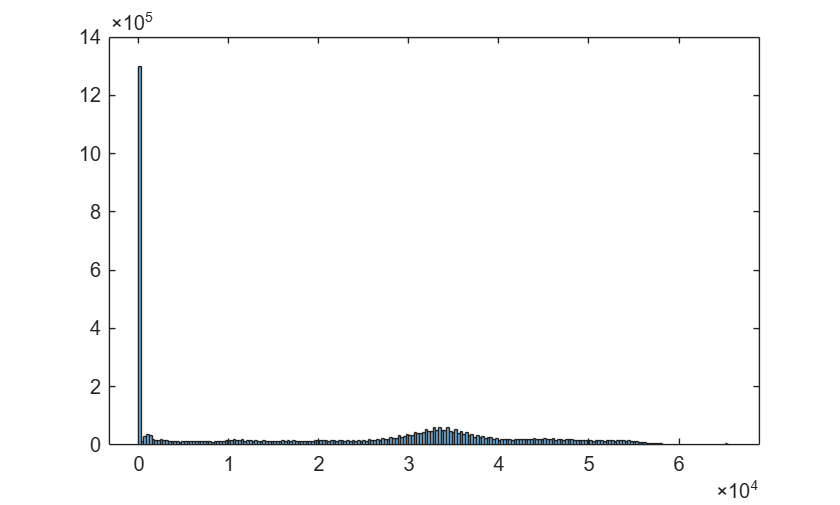

img_adjusted = imadjust(img, [min_value max_value]/ 65535);
figure
histogram(img_adjusted)

## **module 2 **

## **working with medical volumes (3D images)**

first take a look of what are the anatomical planes

to load your medical 3d image use function medicalvolume(your file path)

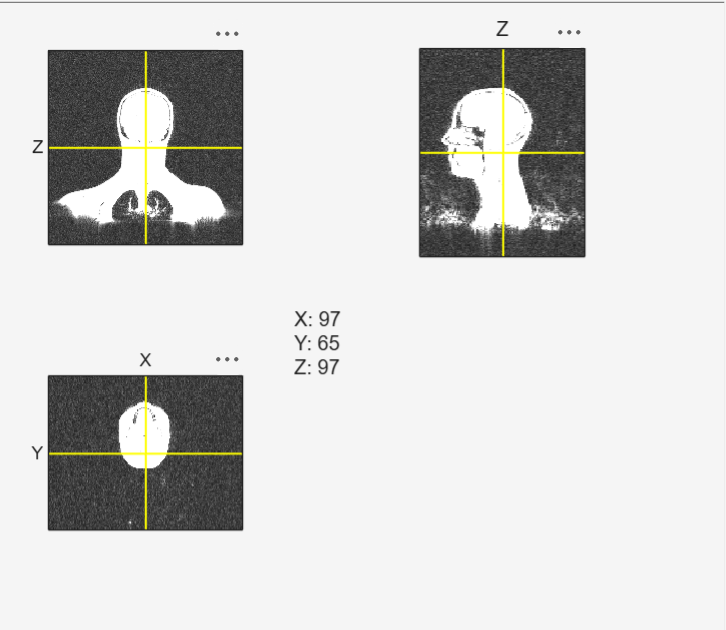


my_mri = medicalVolume("D:\matlab\coursera_content\Medical Image Processing (1)\Data\MRI Images\T1_3T_2018");

%to view the img use orthoslicer viwer, use your live window to adjust your
%brightness and contrast
orthosliceViewer(my_mri)

medical image labeler app 

you have 4 windows of 2D images with an indicator of the name of the plane (sagital, coronal, axial)

to the bottom right you will find a number that indicates where you are in your img 

the fourth window shows 3D redering of the img

to the bottom you can see a slider helping you to move through the image

%TRY VIEWING THE IMG by yourself

this time you have **window level **and **window width** you need to adjust to better see your image

**crosshair navigation** helps you navigate through all the three planes at a time

min_display = min(my_mri.Voxels,[],"all")

min_display = int16
0

max_display = max(my_mri.Voxels,[],"all")

max_display = int16
1399

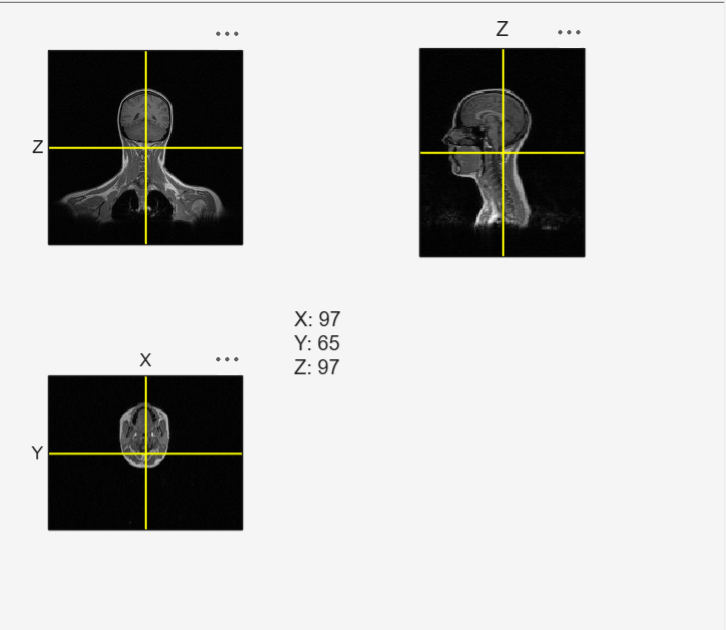

orthosliceViewer(my_mri, DisplayRange= [min_display,max_display])

Extract 2D slice by the function **extractslice()**

what do you need to know to pick your slice?

- **Plane**: determine which Plane (Sagital, coronal, Axial)   

- **sliceNumber**: Put the slice number you want to get   

what will you get?

- The img of the slice and its position in addition to spacing   

Plane = "sagittal"   

Plane = "sagittal"

slice_Number = 60

slice_Number = 60

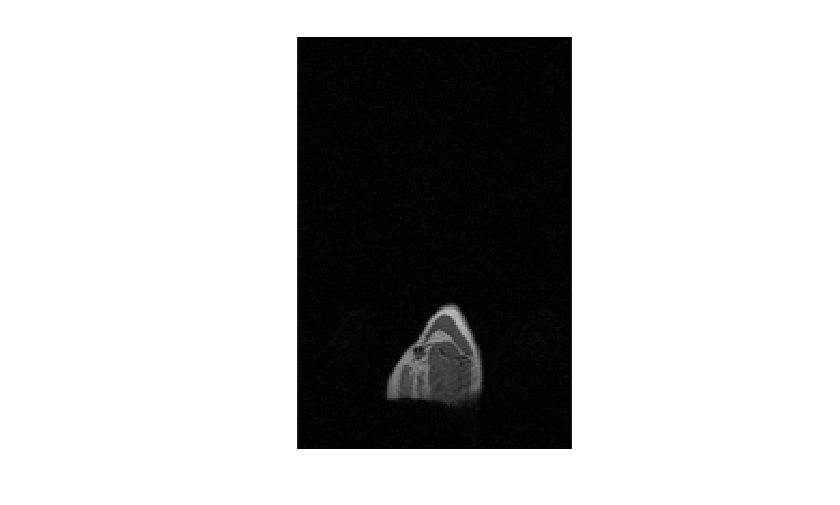

[your_resulted_2d_img, Position, spacing] = extractSlice(my_mri, slice_Number, Plane);
%use imshow for 2d slice
%add min_display and max_display to fix the contrast and brightness 
imshow(your_resulted_2d_img, [min_display,max_display])

**Image Registration**

- **Multi-Modal Registration**   

- Different Modalities (CT, MRI, ...) 

- Different technique, same machine (T1_weighted, T2_weighted)

- Different machines, different sensitivities 

- **Mono-Modal Registration**

- The same everything but over different time 

- The patient anatomy changed

[optimizer, metric] = imregconfig('multimodal');


Your images are differing in:   

- Translation and rotation so it's **Rigid **

- Translation, rotation, and scale so it's **Similarity **

- Translation, rotation, scale, and shear so it's** Affine**

If you have 2 images:

- One is for head and shoulder

- or One is for the head (2 Tesla / 3 Tesla)

So many differences with metadata, and you want to register / align the brain, what should we do?

you will resample one of the 2 images to be similar

second_mri = medicalVolume("D:\matlab\coursera_content\Medical Image Processing (1)\Data\MRI Images\T2_3T_2018")

second_mri =   medicalVolume with properties:

                  Voxels: [256×256×192 int16]
          VolumeGeometry: [1×1 medicalref3d]
            SpatialUnits: "mm"
             Orientation: "sagittal"
            VoxelSpacing: [1 1 1]
            NormalVector: [-1 0 0]
        NumCoronalSlices: 256
       NumSagittalSlices: 192
     NumTransverseSlices: 256
            PlaneMapping: ["coronal"    "transverse"    "sagittal"]
    DataDimensionMeaning: ["posterior"    "inferior"    "left"]
                Modality: "MR"
           WindowCenters: [192×1 double]
            WindowWidths: [192×1 double]


%second_mri geometry will be resampled to look similar to my_mri geometry
resampled3T = resample(second_mri, my_mri.VolumeGeometry);

%now they are ready for registration
your_rigestered_images = imregister(my_mri.Voxels, resampled3T.Voxels, "similarity", optimizer, metric);

when you run your code, you will be waiting for your registered image to appear. but imregister doesn't give medicalvolumes.

you need to create new varaiable and assign your metada of your medicalvolume to it

images_registered = my_mri;
images_registered.Voxels = your_rigestered_images;